%clear();


load("test_signal\sin1d0.mat");
Inp_sine = data{1}.Values.Data

Inp_sine =          0
    0.0754
    0.1508
    0.2262
    0.3016
    0.3769
    0.4523
    0.5276
    0.6029
    0.6782


Measure_sine = data{2}.Values.Data

Measure_sine = 10001×1 single column vector
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0



TimeArr = data{1}.Values.Time

TimeArr =          0
    0.0010
    0.0020
    0.0030
    0.0040
    0.0050
    0.0060
    0.0070
    0.0080
    0.0090



load("test_signal\ramp2d4.mat");
Inp_ramp = data{1}.Values.Data

Inp_ramp =          0
    0.0024
    0.0048
    0.0072
    0.0096
    0.0120
    0.0144
    0.0168
    0.0192
    0.0216


Measure_ramp = data{2}.Values.Data

Measure_ramp = 10001×1 single column vector
  221.6602
  213.9903
  209.3884
  214.7573
  214.7573
  207.8544
  200.9515
  203.2525
  205.5534
  205.5534



load("test_signal\pulse1d0.mat");
Inp_step = data{1}.Values.Data

Inp_step =     12
    12
    12
    12
    12
    12
    12
    12
    12
    12


Measure_step = data{2}.Values.Data

Measure_step = 10001×1 single column vector
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0



load("test_signal\stair1.mat");
Inp_stair = data{1}.Values.Data

Inp_stair =      6
     6
     6
     6
     6
     6
     6
     6
     6
     6


Measure_stair = data{2}.Values.Data

Measure_stair = 10001×1 single column vector
  216.2913
  213.9903
  210.9224
  208.6214
  207.8544
  204.7864
  200.1845
  202.4855
  210.1554
  214.7573



load("test_signal\chirp2.mat");
Inp_chirp = data{1}.Values.Data

Inp_chirp =          0
    0.0063
    0.0126
    0.0189
    0.0252
    0.0314
    0.0377
    0.0440
    0.0503
    0.0566


Measure_chirp = data{2}.Values.Data

Measure_chirp = 10001×1 single column vector
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0



Measure_test_signals = [
    Measure_sine;
    Measure_ramp;
    Measure_step;
    Measure_stair;
    Measure_chirp
];

save("test_signal\Test_Dataframe.mat")

load("test_signal\Test_Dataframe.mat");

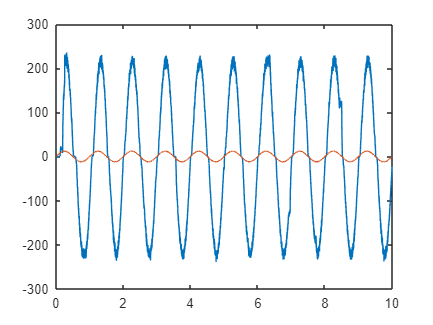

% Plot
figure(Name='Validation Testing Signal')
plot(TimeArr,Measure_sine,TimeArr,Inp_sine)

Test_signal_names = {'Sine', 'Ramp', 'Step', 'Stair', 'Chirp'};

% Store signals in arrays for easy iteration
Inp_test_signals = {Inp_sine, Inp_ramp, Inp_step, Inp_stair, Inp_chirp};
Measure_test_signals = {Measure_sine, Measure_ramp, Measure_step, Measure_stair, Measure_chirp};


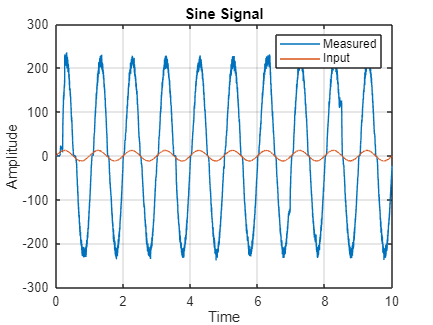

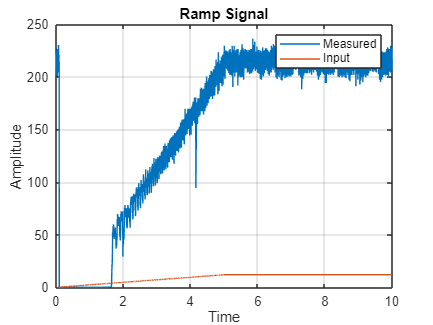

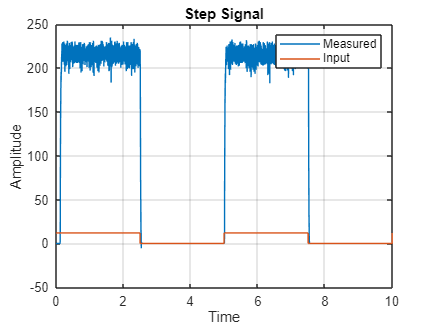

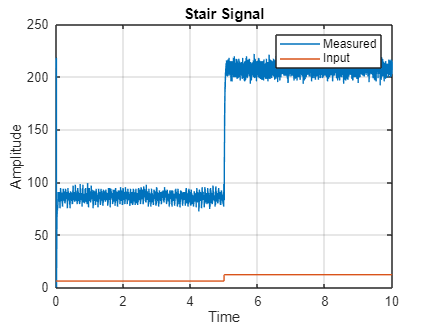

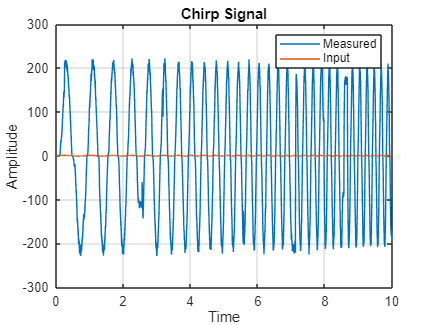


% Loop through each test signal and plot in a separate figure
for i = 1:length(Test_signal_names)
    figure('Name', [Test_signal_names{i}, ' Signal']);
    plot(TimeArr, Measure_test_signals{i}, TimeArr, Inp_test_signals{i});
    title([Test_signal_names{i}, ' Signal']);
    legend('Measured', 'Input');
    xlabel('Time');
    ylabel('Amplitude');
    grid on;
end

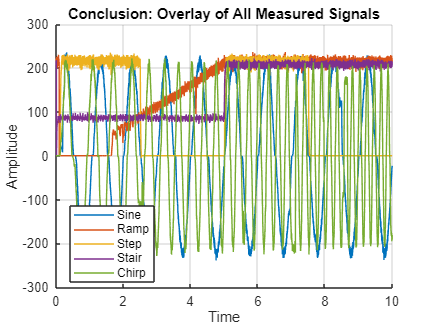


% Final "Conclusion" graph (all measured signals in one plot)
figure('Name', 'Conclusion: Overlay of All Measured Signals');
hold on;
for i = 1:length(Test_signal_names)
    plot(TimeArr, Measure_test_signals{i});
end
hold off;
title('Conclusion: Overlay of All Measured Signals');
legend(Test_signal_names, 'Location', 'best');
xlabel('Time');
ylabel('Amplitude');
grid on;

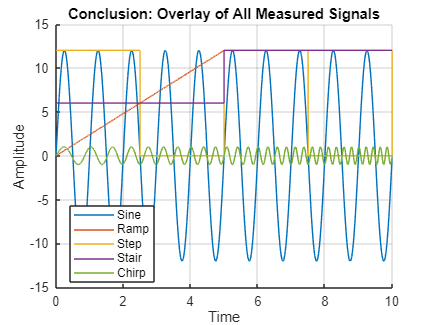


% Final "Conclusion" graph (all measured signals in one plot)
figure('Name', 'Conclusion: Overlay of All Input Test Signals');
hold on;
for i = 1:length(Test_signal_names)
    plot(TimeArr, Inp_test_signals{i});
end
hold off;
title('Conclusion: Overlay of All Measured Signals');
legend(Test_signal_names, 'Location', 'best');
xlabel('Time');
ylabel('Amplitude');
grid on;

load("model_predict\predict_sin01.mat");
model_predict_signals = data.Data

model_predict_signals =          0         0         0         0         0
    0.0104    0.0003    2.5496    1.2748    0.0104
    0.0466    0.0015    8.8620    4.4310    0.0466
    0.1229    0.0039   15.3703    7.6852    0.1229
    0.2395    0.0076   21.7070   10.8535    0.2396
    0.3952    0.0126   27.8398   13.9199    0.3955
    0.5889    0.0187   33.7715   16.8858    0.5893
    0.8191    0.0261   39.5083   19.7542    0.8198
    1.0848    0.0345   45.0565   22.5283    1.0859
    1.3847    0.0441   50.4223   25.2112    1.3863
